clear all
cd /media/DataMOBsRAIDN/ProjectEmbReact/Figures/RiskAssessment
load('RiskAssessMat_0.mat')
BefTime=12; % in seconds
tps=[0:0.01:BefTime*2];
Structures={'B','P','H'};
StructurePairs={'B_P','B_H','P_H'};
SessTypes={'TestPost','UMazeCond','TestPost_EyeShock','UMazeCond_EyeShock','UMazeCondBlockedShock_EyeShock','UMazeCondBlockedSafe_EyeShock'};


AllMov=[];
AllPos=[];
AllEKG=[];
for st=1:length(Structures)
    AllSpec.(Structures{st})=[];
    AllLFP.(Structures{st})=[];
end
AllSpec.H_High=[];
for st=1:length(StructurePairs)
    AllCoh.(StructurePairs{st})=[];
end
for ss=1:length(SessTypes)
    for mm=1:length(RiskAssess.(SessTypes{ss}).ToShockMov)
        if not(isempty(RiskAssess.(SessTypes{ss}).ToShockMov{mm}))
            AllMov=[AllMov;RiskAssess.(SessTypes{ss}).ToShockMov{mm}];
            for st=1:length(Structures)
                AllSpec.(Structures{st})=cat(3,AllSpec.(Structures{st}),RiskAssess.(SessTypes{ss}).ToShockSpec.(Structures{st}){mm}(:,1:207,:));
                AllLFP.(Structures{st})=[AllLFP.(Structures{st}),RiskAssess.(SessTypes{ss}).ToShockLFP.(Structures{st}){mm}];
            end
            try
            AllSpec.H_High=[AllSpec.H_High,RiskAssess.(SessTypes{ss}).ToShockSpec.H_High{mm}];
            end
            for st=1:length(StructurePairs)
                AllCoh.(StructurePairs{st})=cat(3,AllCoh.(StructurePairs{st}),RiskAssess.(SessTypes{ss}).ToShockCoh.(StructurePairs{st}){mm});
            end
            AllEKG=[AllEKG;RiskAssess.(SessTypes{ss}).ToShockEKG{mm}];
            AllPos=[AllPos;RiskAssess.(SessTypes{ss}).ToShockPos{mm}];
        end
    end
end

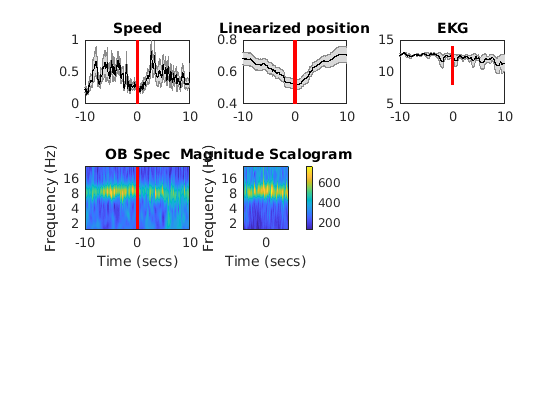

Error using matlab.graphics.axis.decorator.NumericRuler/forceFullUpdate
Operation terminated by user

Error in matlab.graphics.illustration.ColorBar/get.Label

Error in plotscalogramfreq_SB (line 64)
hcol.Label.String = 'Magnitude';

figure
subplot(3,3,1)
shadedErrorBar(tps-BefTime,nanmean(AllMov(:,:)),stdError(AllMov(:,:)));
xlim([-10 10])
hold on
line([0 0],ylim,'color','r','linewidth',3)
title('Speed')
subplot(3,3,2)
shadedErrorBar(tps-BefTime,nanmean(AllPos(:,:)),stdError(AllPos(:,:)));
xlim([-10 10])
hold on
line([0 0],ylim,'color','r','linewidth',3)
title('Linearized position')
subplot(3,3,3)
shadedErrorBar(tps(20:end-20)-BefTime,nanmean(AllEKG(:,20:end-20)),stdError(AllEKG(:,20:end-20)));
xlim([-10 10])
hold on
line([0 0],ylim,'color','r','linewidth',3)
title('EKG')
subplot(3,3,4)
plotscalogramfreq_SB(Wavelet.OutParams.FourierFactor,Wavelet.OutParams.sigmaT,mean(AllSpec.B,3)',freqSpec,tps-BefTime,Wavelet.OutParams.normalizedfreq)
colorbar off
xlim([-10 10])
hold on
line([0 0],ylim,'color','r','linewidth',3)
title('OB Spec')
subplot(3,3,5)
plotscalogramfreq_SB(Wavelet.OutParams.FourierFactor,Wavelet.OutParams.sigmaT,mean(AllSpec.H,3)',freqSpec,tps-BefTime,Wavelet.OutParams.normalizedfreq)

colorbar off
xlim([-10 10])
hold on
line([0 0],ylim,'color','r','linewidth',3)
title('HPC spec')
subplot(3,3,6)
plotscalogramfreq_SB(Wavelet.OutParams.FourierFactor,Wavelet.OutParams.sigmaT,mean(AllSpec.P,3)',freqSpec,tps-BefTime,Wavelet.OutParams.normalizedfreq)
colorbar off
xlim([-10 10])
hold on
line([0 0],ylim,'color','r','linewidth',3)
title('PFCx spec')
subplot(3,3,7)
plotscalogramfreq_SB(Wavelet.OutParams.FourierFactor,Wavelet.OutParams.sigmaT,mean(AllCoh.B_P,3)',freqCoh,tps-BefTime,Wavelet.OutParams.normalizedfreq)
colorbar off
xlim([-10 10])
hold on
line([0 0],ylim,'color','r','linewidth',3)
title('B-P coh')
subplot(3,3,8)
plotscalogramfreq_SB(Wavelet.OutParams.FourierFactor,Wavelet.OutParams.sigmaT,mean(AllCoh.B_H,3)',freqCoh,tps-BefTime,Wavelet.OutParams.normalizedfreq)
colorbar off
xlim([-10 10])
hold on
line([0 0],ylim,'color','r','linewidth',3)
title('B-H coh')
subplot(3,3,9)
plotscalogramfreq_SB(Wavelet.OutParams.FourierFactor,Wavelet.OutParams.sigmaT,mean(AllCoh.P_H,3)',freqCoh,tps-BefTime,Wavelet.OutParams.normalizedfreq)
colorbar off
xlim([-10 10])
hold on
line([0 0],ylim,'color','r','linewidth',3)
title('P-H Coh')

FreqBand=find(freqSpec>8&freqSpec<12);
figure
for st=1:length(Structures)
    subplot(2,3,st)
    a=zscore(squeeze(nanmean(AllSpec.(Structures{st})(:,FreqBand,:),2)))';
    tpsbis=[-12+24/size(a,2):24/size(a,2):12];
    [hl,hp]=boundedline(tpsbis,nanmean(a),[stdError(a);stdError(a)]','alpha'),hold on;
    xlim([-12 12])
    ylim([-1 1])
    title([ Structures{st} 'Spec'])
    line([0 0],ylim,'color','r','linewidth',2) 
end

hl = 13.0006

hp = 1.0004

hl = 411.0001

hp = 410.0001

hl = 413.0001

hp = 412.0001

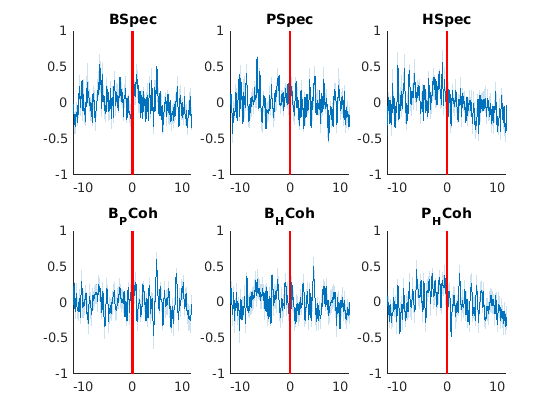

hl = 415.0001

hp = 414.0001

hl = 417.0001

hp = 416.0001

hl = 419.0001

hp = 418.0001

FreqBand=find(freqCoh>8&freqCoh<12);
for st=1:length(Structures)
    subplot(2,3,st+3)
    a=zscore(squeeze(nanmean(AllCoh.(StructurePairs{st})(:,FreqBand,:),2)))';
    tpsbis=[-12+24/size(a,2):24/size(a,2):12];
    [hl,hp]=boundedline(tpsbis,nanmean(a),[stdError(a);stdError(a)]','alpha'),hold on;
    xlim([-12 12])
    ylim([-1 1])
    title([ StructurePairs{st} 'Coh'])
    line([0 0],ylim,'color','r','linewidth',2) 
end

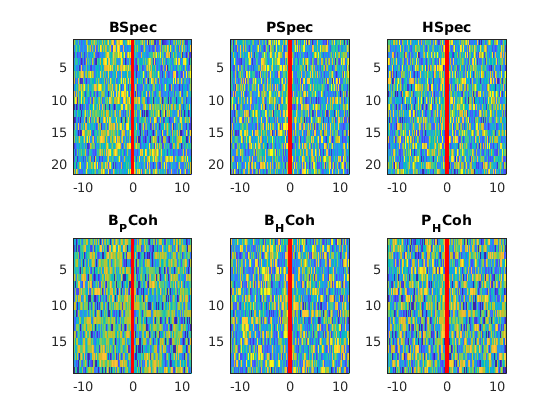

FreqBand=find(freqSpec>8&freqSpec<12);
figure
for st=1:length(Structures)
    subplot(2,3,st)
    a=squeeze(nanmean(AllSpec.(Structures{st})(:,FreqBand,:),2))';
    tpsbis=[-12+24/size(a,2):24/size(a,2):12];
    imagesc(tpsbis,1:size(a,1),zscore(a')'),hold on;
    xlim([-12 12])
    caxis([-2 2])
    title([ Structures{st} 'Spec'])
    line([0 0],ylim,'color','r','linewidth',3) 
end
FreqBand=find(freqCoh>8&freqCoh<12);
for st=1:length(Structures)
    subplot(2,3,st+3)
    a=squeeze(nanmean(AllCoh.(StructurePairs{st})(:,FreqBand,:),2))';
    tpsbis=[-12+24/size(a,2):24/size(a,2):12];
    imagesc(tpsbis,1:size(a,1),zscore(a')'),hold on;
    xlim([-12 12])
        caxis([-2 2])
    title([ StructurePairs{st} 'Coh'])
    line([0 0],ylim,'color','r','linewidth',3) 
end